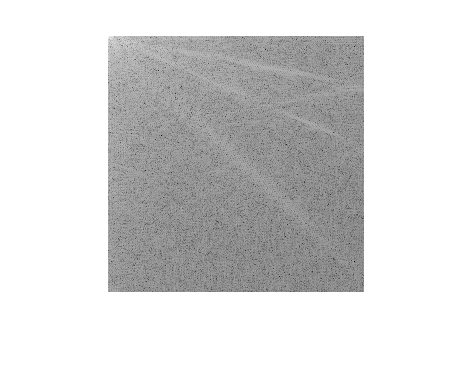

image = imread('Important_files/cameraman.tif');

dct_image = dct2(image);

imshow(log(abs(dct_image)), []);

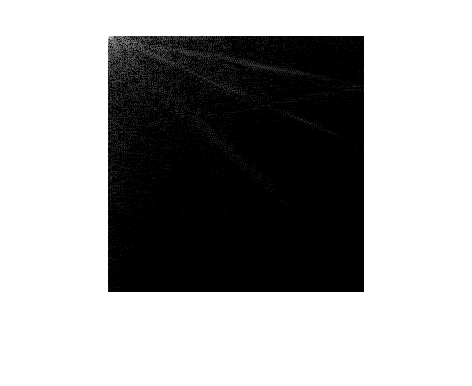


magnitudes = abs(dct_image);

sorted_mags = sort(magnitudes(:));

index = round(length(sorted_mags) * 0.8);

threshold = sorted_mags(index);

dct_image(abs(dct_image) < threshold) = 0;

imshow(log(abs(dct_image)), []);

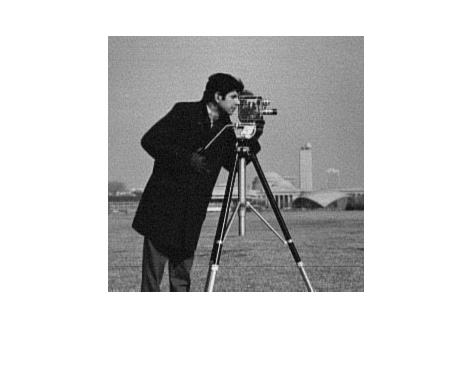

Undefined function or variable 'zz'.


reconstructed = idct2(dct_image);

imshow(reconstructed, []);

z_mask = zeros(256)

z_mask =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

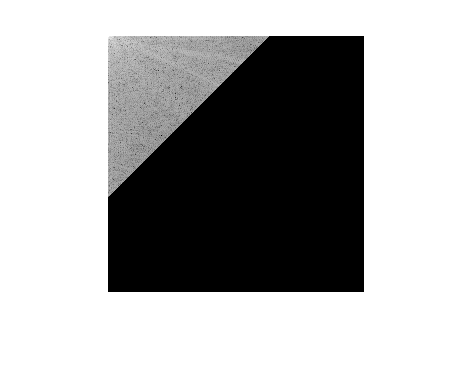


current_length = 161;
for i = 1:161
    z_mask(1:162-i,i) = 1;
end

dct_image = dct2(image);

dct_image = dct_image .* z_mask;

imshow(log(abs(dct_image)), [])

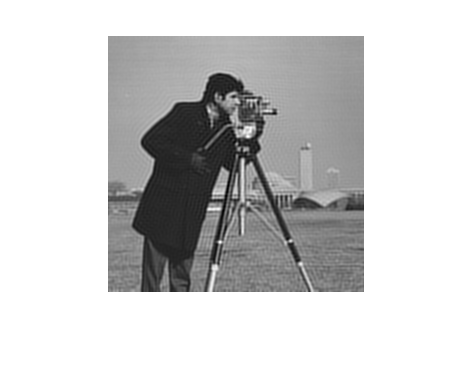


reconstructed = idct2(dct_image);

imshow(reconstructed, []);